 x1=5;
x2=7;
x3=11;
x4=13;
L=pi;
h=1;

n=5

n = 5

nn=[1:1:n]

nn =      1     2     3     4     5



syms x
syms al
al=sym(pi/2)

$$al = \frac{\pi }{2}$$

syms sn
f= piecewise(abs(x)>al,sym(1),abs(x)<=al,sym(0))

$$f = \left\{ \begin{array}{cl} 1 & \text{ if }\frac{\pi }{2}<\left|x\right|\\ 0 & \text{ if }\left|x\right|\leq \frac{\pi }{2} \end{array}\right.$$



symvar(f)

$$ans = x$$

ezplot(f)

Error using ezplot>ezplot1 (line 460)
The input character vector must be an expression.  Implicit functions of a single variable are not supported.

Error in ezplot (line 158)
                [hp, cax] = ezplot1(cax, f{1}, vars, labels, args{:});

Error in 

syms A
syms xu


L = 10


A=1

A = 1

xu = 10

xu = 10

L = xu

%f = piecewise(0<=x<=xu,A*(1- ((2*x-xu)/(xu))^2 ),x<0,sym(0),x>xu,sym(0))
f = piecewise(-L/2<=x<=L/2,A*(1- ((2*x)/(xu))^2),x<-L/2,0,x>L/2,0 )

$$f = \left\{ \begin{array}{cl} 1-\frac{x^{2}}{25} & \text{ if }x\in \left[-5,5\right]\\ 0 & \text{ if }5<x\vee x<-5 \end{array}\right.$$


symvar(f)

$$ans = x$$

xx = [-10:0.1:10]

xx =   -10.0000   -9.9000   -9.8000   -9.7000   -9.6000   -9.5000   -9.4000   -9.3000   -9.2000   -9.1000   -9.0000   -8.9000   -8.8000   -8.7000   -8.6000   -8.5000   -8.4000   -8.3000   -8.2000   -8.1000   -8.0000   -7.9000   -7.8000   -7.7000   -7.6000   -7.5000   -7.4000   -7.3000   -7.2000   -7.1000   -7.0000   -6.9000   -6.8000   -6.7000   -6.6000   -6.5000   -6.4000   -6.3000   -6.2000   -6.1000   -6.0000   -5.9000   -5.8000   -5.7000   -5.6000   -5.5000   -5.4000   -5.3000   -5.2000   -5.1000


ff = subs(f,x,xx)

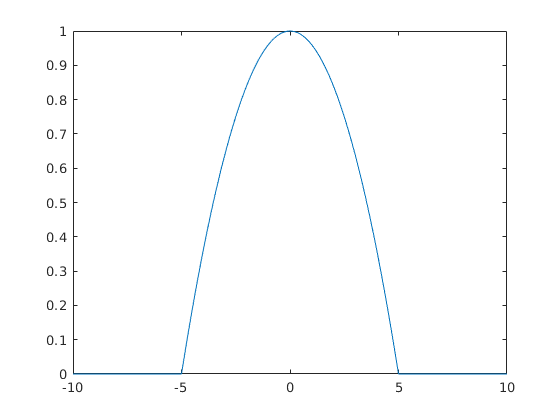


plot(xx,ff)



F = 2*int(f*cos(2*pi*t*x),x,0,xu/2)

$$F = \frac{\sin\left(10\,\pi \,t\right)-10\,\pi \,t\,\cos\left(10\,\pi \,t\right)}{50\,t^{3}\,\pi^{3}}$$


symvar(F)

$$ans = t$$

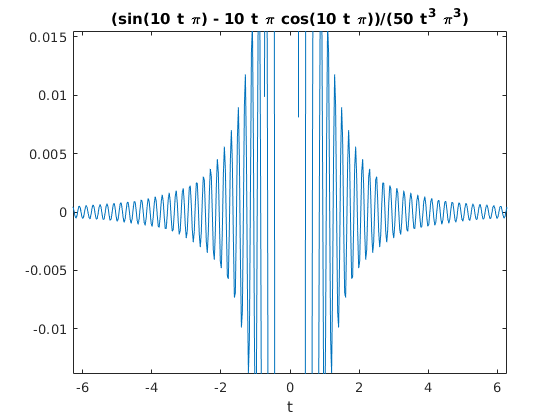

ezplot(F)


%Double A
a0=(1/L)*int(f,-L,L)

$$a0 = -\frac{1911387046407553\,\pi^{2}\,\left(\pi -15\right)}{450359962737049600}$$

a = (1/L)*int(f*cos(pi*sn*x/L),x,-L,L);
aa=subs(a,sn,nn);
aa=double(aa)

aa =    -0.1746   -0.0200   -0.0194   -0.0050   -0.0070


%Double B
b = (1/L)*int(f*sin(pi*sn*x/L),x,-L,L);
bb=subs(b,sn,nn);
bb=double(bb)

bb =     0.3253   -0.1372    0.0933   -0.0686    0.0553



%Single B
b = (2/L)*int(f*sin(pi*sn*x/L),x,0,L);
bb=subs(b,sn,nn);
bb=double(bb)
aa=zeros(1,n);
a0=0;


%Single A
%syms L
a0=(1/L)*int(f,-L,L)

$$a0 = -\frac{1911387046407553\,\pi^{2}\,\left(\pi -15\right)}{450359962737049600}$$


a = (2/L)*int(f*cos(pi*sn*x/L),x,0,L)

$$a = -\frac{5734161139222659\,\left(10\,\mathrm{sn}-2\,\sin\left(\pi \,\mathrm{sn}\right)-10\,\mathrm{sn}\,\cos\left(\pi \,\mathrm{sn}\right)-10\,\pi \,{\mathrm{sn}}^{2}\,\sin\left(\pi \,\mathrm{sn}\right)+{\mathrm{sn}}^{2}\,\pi^{2}\,\sin\left(\pi \,\mathrm{sn}\right)+2\,\pi \,\mathrm{sn}\,\cos\left(\pi \,\mathrm{sn}\right)\right)}{225179981368524800\,{\mathrm{sn}}^{3}}$$


aa=subs(a,sn,nn)

$$aa = \left(\begin{array}{ccccc} \frac{5734161139222659\,\pi }{112589990684262400}-\frac{5734161139222659}{11258999068426240} & -\frac{5734161139222659\,\pi }{450359962737049600} & \frac{1911387046407553\,\pi }{337769972052787200}-\frac{1911387046407553}{33776997205278720} & -\frac{5734161139222659\,\pi }{1801439850948198400} & \frac{5734161139222659\,\pi }{2814749767106560000}-\frac{5734161139222659}{281474976710656000} \end{array}\right)$$

aa=double(aa)

aa =    -0.3493   -0.0400   -0.0388   -0.0100   -0.0140


bb=zeros(1,n);

syms al
syms t
%bb=[0.9081,-0.0986,-0.5223,0.0154]
ffou=(a0/2)+sum(aa.*cos(pi.*nn.*x./L)+bb.*sin(pi.*nn.*x./L),0);
al = sym(1)

$$al = 1$$

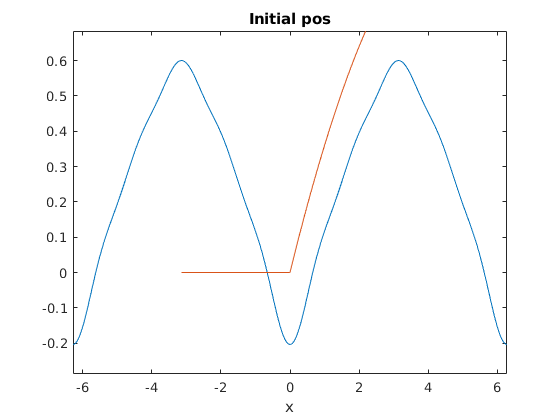

%t = sym(42)
ezplot(ffou)
title("Initial pos"),
hold on
ffou=sum( bb.*cos(al.*pi.*nn.*t./L).*sin(pi.*nn.*x./L));
xx=linspace(-L,L,1000);
fpl=subs(f,x,xx);%f plot
plot(xx,fpl);
hold off

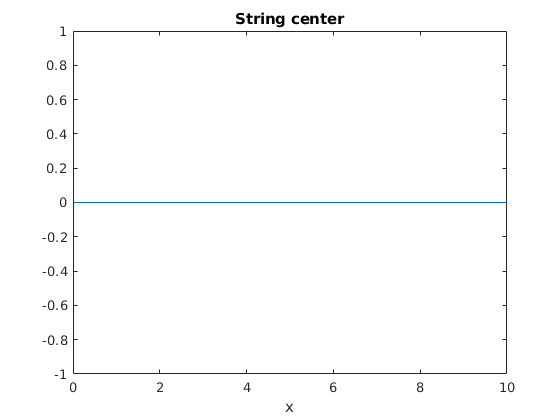




ezplot(subs(ffou,x,L/2),0,10)
title("String center")

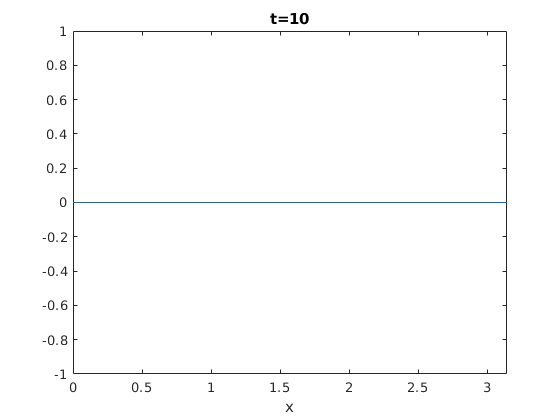


ezplot(subs(ffou,t,10),[0,L])
title("t=10")

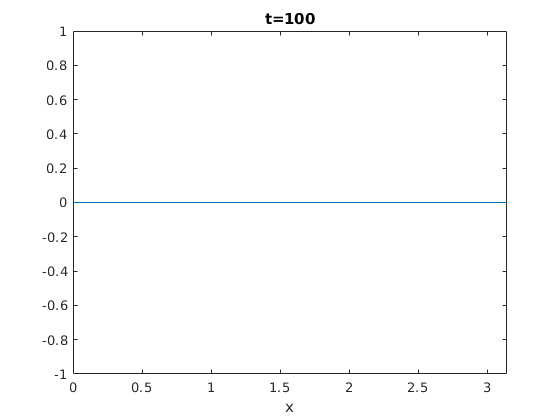

ezplot(subs(ffou,t,100),[0,L])
title("t=100")

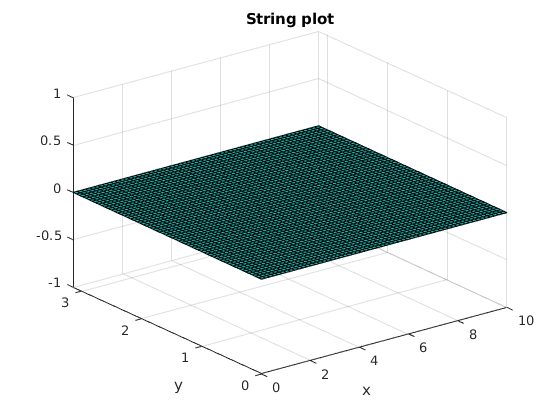


ezsurf(ffou,[0,10,0,L])
title("String plot")

%ezplot(ffou,0,L)
%hold off



%Parseval
p = (1/L)*int((f*f),x,-L,L)

$$p = \frac{5734161139222659\,\pi }{18014398509481984}$$

pp=a0/2+sum(aa.^2.+bb.^2)

$$pp = \frac{5734161139222659\,\pi }{36028797018963968}+\frac{8934199376727365}{18014398509481984}$$

double(pp)

ans = 0.9959

b = (2/L)*int(f*sin(pi*sn*x/L),x,0,L);
bb=subs(b,sn,nn);
bb=double(bb)

bb =     0.6366   -0.6366    0.2122         0    0.1273   -0.2122    0.0909         0    0.0707   -0.1273    0.0579         0    0.0490   -0.0909    0.0424         0    0.0374   -0.0707    0.0335         0    0.0303   -0.0579    0.0277         0    0.0255   -0.0490    0.0236         0    0.0220   -0.0424    0.0205         0    0.0193   -0.0374    0.0182         0    0.0172   -0.0335    0.0163         0    0.0155   -0.0303    0.0148         0    0.0141   -0.0277    0.0135         0    0.0130   -0.0255


p1 = (2/L)*int((f*f),x,0,L)

$$p1 = \frac{5734161139222659\,\pi }{18014398509481984}$$

pp1=sum(bb.^2)

pp1 = 0.9882

double(pp1)

ans = 0.9882

%ezplot(xx,yy)